# Herein, we use an implicit solver to solve the system of ODEs defining our system

By, Mamba Phelelani Eshmael (217058111)

BSc Chemical Engineering, University of KwaZulu-Natal, South Africa

Contact: mambaphelelani@gmail.com / PE-Mamba@outlook.com / 217058111@stu.ukzn.ac.za

Supervisior(s): Professor David Lokhat and Dr Machiel Wayne (Lecturers and researchers, UKZN)

clear
D_tube = 1.56;
EO_in = 6;
NH3_EO_ratio = 50;                          % Ammonia to Ethylene Oxide ratio.
NH3_in = EO_in*NH3_EO_ratio;                %Ammonia inlet flowrate in mol/s
pressure = 13;                              % Inlet Pressure in MPa.
init_conds = [0,0,0,EO_in,NH3_in,375,pressure];
Opt    = odeset('Refine',20);
z_span = [0,5];                             % Integration Span for reaction length
[Z,sol] = ode15s(@(Z,F)system_of_ODEs_heterogenous(Z,F,D_tube),z_span,init_conds, Opt); % Solving the ODEs simultanously
[Pos,bulk_density,Q,r1,Weisz_Prater,Mears,mass_flow,mu_avag] = system_of_ODEs_heterogenous(Z.',sol.',D_tube');
figure

Plotting the profiles of species along reactor length

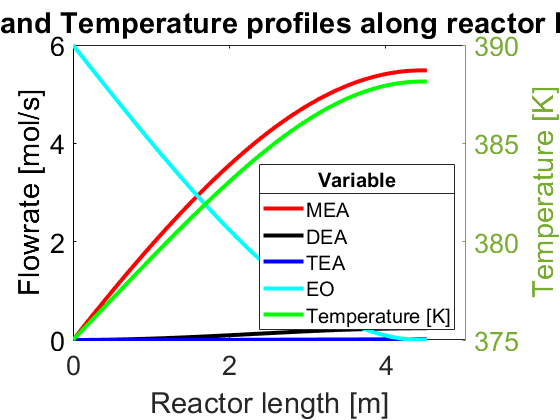

vec = sol(:,4);
for i = 1:numel(vec)
    int_end = 0;
    if vec(i) <0
        int_end = i - 1;
        break
    end    
end
if int_end == 0
            int_end = length(vec);
end
for j = 1:int_end
    MEA(j)   = sol(j,1);
    DEA(j)   = sol(j,2);
    TEA(j)   = sol(j,3);
    EO(j)    = sol(j,4);
    NH3(j)   = sol(j,5);
    Temp(j)  = sol(j,6);
    Pres(j)  = sol(j,7);
    Len(j)   = Z(j);
end

Rec_length = max(Len);                                % The final length of reactor 
L_D_ratio = Rec_length/D_tube;
figure
plot(Len,MEA,'color','r',"DisplayName",'MEA',"LineStyle","-","LineWidth",3);
hold on
plot(Len,DEA,'color','k',"DisplayName",'DEA',"LineStyle","-","LineWidth",3);
hold on
plot(Len,TEA,'color','b',"DisplayName",'TEA',"LineStyle","-","LineWidth",3);
hold on
plot(Len,EO,'color','c',"DisplayName",'EO',"LineStyle","-","LineWidth",3);
hold on
ylabel('Flowrate [mol/s]','FontSize',25)
%plot(Z,sol(:,5),'color','m',"DisplayName",'NH_3',"LineStyle","-","LineWidth",3);
yyaxis right
hold on
plot(Len,Temp,'color','g',"DisplayName",'Temperature [K]',"LineStyle","-","LineWidth",3);
hold on
title("Specie and Temperature profiles along reactor length","FontSize",30)
ylabel('Temperature [K]','FontSize',25)
xlabel('Reactor length [m]','FontSize',25)
leg = legend('show','location','southeast','FontSize',15);
title(leg,'Variable','Interpreter',"latex","FontSize",15,"InterpreterMode","auto")
legend('show','location','northwest')
xlim([0 (Rec_length + 0.5)])
set(gca,'FontSize',20)

It can be seen that the is technically no TEA produced by our catalyst.

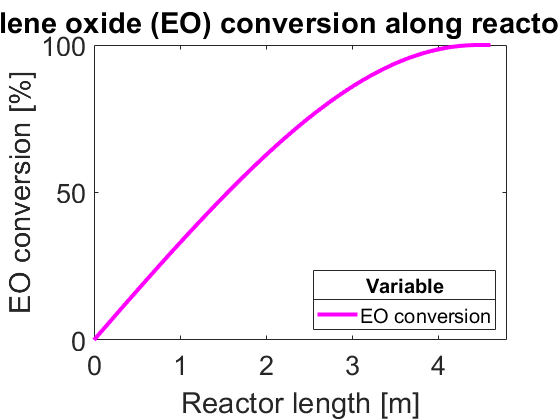

EO_out = min(sol(:,4));
EO_conversion = ((EO_in - sol(:,4))./(EO_in))*100;
figure
plot(Z,EO_conversion,'color','m',"DisplayName",'EO conversion',"LineStyle","-","LineWidth",3);
title("Ethylene oxide (EO) conversion along reactor length","FontSize",30)
ylabel('EO conversion [%]','FontSize',25)
xlabel('Reactor length [m]','FontSize',25)
leg = legend('show','location','southeast','FontSize',15);
title(leg,'Variable','Interpreter',"latex","FontSize",15,"InterpreterMode","auto")
legend('show','location','northwest')
set(gca,'FontSize',20)
xlim([0 4.8])
ylim([0 100])

NH3 = min(sol(:,5));
MEA = max(sol(:,1));
DEA = max(sol(:,2));
TEA = max(sol(:,3));
product_flowrate = MEA + DEA + TEA;
outlet = NH3 + MEA + DEA + EO_out + TEA;

MEA_ratio = (MEA/product_flowrate)*100

MEA_ratio = 95.5608

DEA_ratio = (DEA/product_flowrate)*100

DEA_ratio = 4.2061

TEA_ratio = (TEA/product_flowrate)*100

TEA_ratio = 0.2331

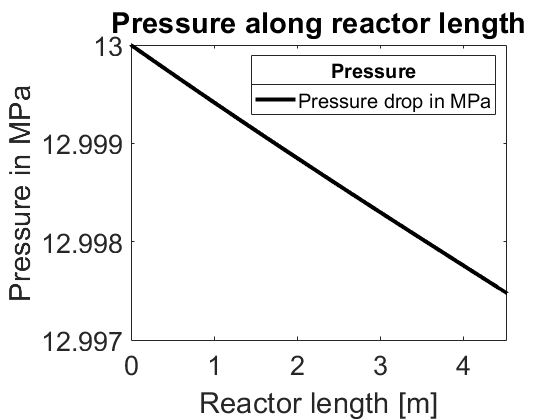

figure
plot(Len,Pres,'color','k',"DisplayName",'Pressure drop in MPa',"LineStyle","-","LineWidth",3);
title("Pressure along reactor length","FontSize",30)
ylabel('Pressure in MPa','FontSize',25)
xlabel('Reactor length [m]','FontSize',25)
leg = legend('show','location','northeast','FontSize',15);
title(leg,'Pressure','Interpreter',"latex","FontSize",15,"InterpreterMode","auto")
set(gca,'FontSize',20)